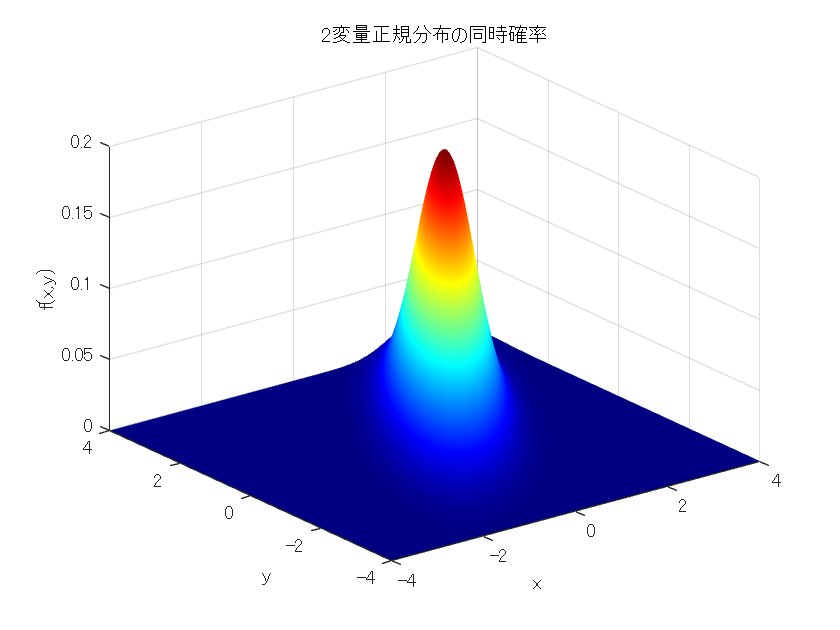

%--------------------------------------------
% 2変量正規分布の3Dプロット & 2D等高線プロット例
%--------------------------------------------
clear;

% パラメータ設定
mu_x = 1;
mu_y = 1;
sigma_x = 1;
sigma_y = sqrt(2);
% sigma_y = 0.8;
rho = 0.8;

mu = [mu_x, mu_y];
% 分散共分散行列
Sigma = [sigma_x^2              rho*sigma_x*sigma_y; 
         rho*sigma_x*sigma_y    sigma_y^2];

% プロット用の格子点を生成
x1 = -4:0.1:4;         % x方向の値
x2 = -4:0.1:4;         % y方向の値
[x, y] = meshgrid(x1, x2);

% 2変量正規分布の確率密度関数を計算
F = mvnpdf([x(:), y(:)], mu, Sigma);
F = reshape(F, length(x2), length(x1));

%=== 1) 3次元サーフェスプロット ===
figure('Name','3D Surface');
surf(x1, x2, F);
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('2変量正規分布の同時確率');
shading interp;        % 補間表示
colormap jet;          % カラーマップ設定

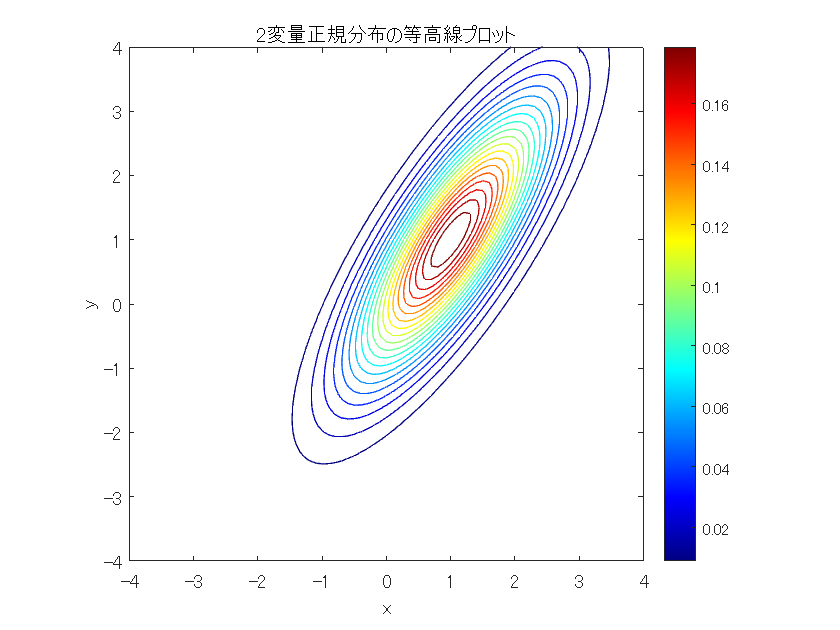


%=== 2) 2次元等高線プロット ===
figure('Name','2D Contour');
contour(x1, x2, F, 20); % 第3引数で等高線の数(20本)を指定
xlabel('x');
ylabel('y');
title('2変量正規分布の等高線プロット');
axis equal;             % スケールを等倍にする
colormap jet;           % カラーマップ設定
colorbar;               % カラーバー表示

条件付期待値のプロット

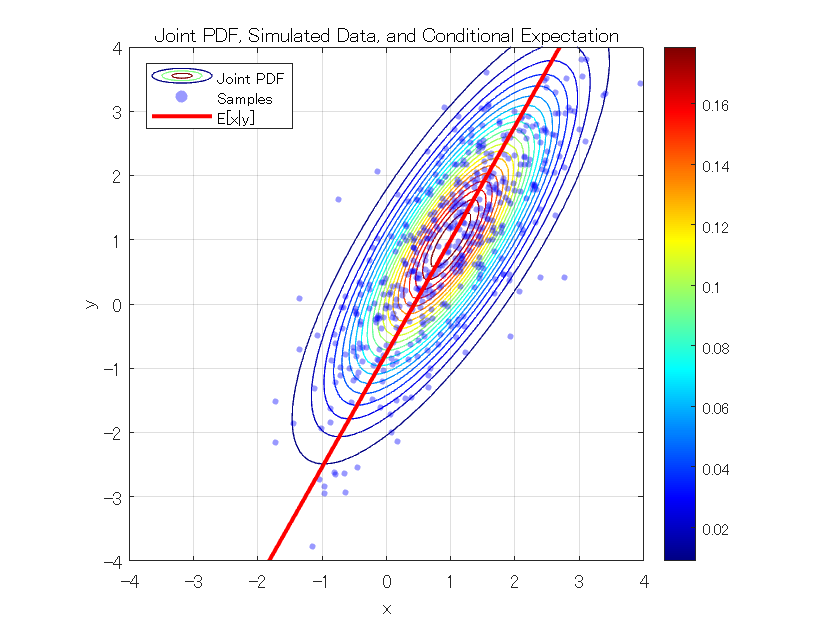


% サンプルの設定
rng(1,"twister");
num_samples = 500;
xy_samples = mvnrnd(mu, Sigma, num_samples);

% 条件付期待値の式
mu_x_given_y = mu_x + rho * (sigma_x / sigma_y) * (y(:, 1) - mu_y);

figure;
contour(x, y, F, 20);
axis equal;             % スケールを等倍にする
colormap jet;           % カラーマップ設定
colorbar;               % カラーバー表示
hold on;

% Scatter plot of samples
scatter(xy_samples(:, 1), xy_samples(:, 2), 10, 'b', 'filled', 'MarkerFaceAlpha', 0.4);

% Plot Conditional Expectation Curve
plot(mu_x_given_y, y(:, 1), 'r', 'LineWidth', 2);


% orthogonal_contour_x = mu_x + ((sigma_x^2 - sigma_y^2) + sqrt((sigma_x^2 - sigma_y^2)^2 + 4*rho^2*sigma_x^2*sigma_y^2) ) / (2*rho*sigma_x*sigma_y) * (y(:, 1) - mu_y);
% plot(orthogonal_contour_x, y(:, 1), 'c--', 'LineWidth', 2);


xlabel('x');
ylabel('y');
title('Joint PDF, Simulated Data, and Conditional Expectation');
grid on;
legend('Joint PDF', 'Samples', 'E[x|y]', 'Location', 'northwest');
% legend('Joint PDF', 'Samples', 'E[x|y]', 'temp', 'Location', 'northwest');
xlim([-4 4]);
ylim([-4 4]);